format long
syms x
p_sym = (1/216)*x^4 + (5/72)*x^3 + (25/72)*x^2 - x + (125/216); %characteristic polynomial
lambda_sym = double(solve(p_sym, x)); %solves the characteristic polynomial

%roots of the char. poly.
l_1 = lambda_sym(1)

l_1 =      1


l_2 = lambda_sym(2)

l_2 =    1.132264310167907


l_3 = lambda_sym(3)

l_3 =  -8.566132155083954 - 6.084376001892327i


l_4 = lambda_sym(4)

l_4 =  -8.566132155083954 + 6.084376001892327i


C1 =    1.394966547839202


C2 =   -0.394966547837642


C3 =      -7.799359910209676e-13 - 4.795309476595979e-13i


C4 =      -7.799359910209676e-13 + 4.795309476595979e-13i


r_W =    1.000000000000000
   0.947760022019941
   0.888610559414605
   0.821637732285235
   0.745806815933439
   0.659945920667683
   0.562730241762116
   0.452658029460422
   0.327828298474595
   0.189715450506131


C1 =    1.001972147715811


C2 =   -0.001972147715810


C3 =      -5.063498898111658e-54 - 7.553418228860955e-54i


C4 =      -5.063498898111658e-54 + 7.553418228860955e-54i


r_W =    1.000000000000000
   0.999739155242819
   0.999443810033769
   0.999109401194382
   0.998730762000540
   0.998302042354921
   0.997816618401120
   0.997266990182930
   0.996644665767612
   0.995940030042802


C1 =    1.000003950886881


C2 =     -3.950886880975333e-06


C3 =     -4.155063387228756e-106 -7.641610542710830e-105i


C4 =     -4.155063387228756e-106 +7.641610542710830e-105i


r_W =    1.000000000000000
   0.999999477438672
   0.999998885761131
   0.999998215825767
   0.999997457281866
   0.999996598409678
   0.999995625939352
   0.999994524845910
   0.999993278117104
   0.999991866490571


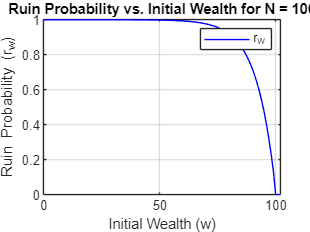


N_values = [10, 50, 100]; %different values for N (target wealth)
n = length(N_values);

for i = 1:n
    N = N_values(i);

    % Solve for coefficients given initial conditions r_0 = 1, r_N = 0,
    % r_(N) = 0, r_(N+1) = 0 
  
    syms c_1 c_2 c_3 c_4;
    [c_1, c_2, c_3, c_4] = solve( ...
    c_1 + c_2 + c_3 + c_4 == 1, ...
    ((c_1)*(l_1)^(N)) + ((c_2)*(l_2)^(N)) + ((c_3)*(l_3)^(N)) + ((c_4)*(l_4)^(N)) == 0, ...
    ((c_1)*(l_1)^(N+1)) + ((c_2)*(l_2)^(N+1)) + ((c_3)*(l_3)^(N+1)) + ((c_4)*(l_4)^(N+1)) == 0,  ...
    ((c_1)*(l_1)^(N+2)) + ((c_2)*(l_2)^(N+2)) + ((c_3)*(l_3)^(N+2)) + ((c_4)*(l_4)^(N+2)) == 0); % Solve for these variables and return struct

C1 = double(c_1) %stores the values of coefficients
C2 = double(c_2)
C3 = double(c_3)
C4 = double(c_4)

    r_W = zeros(1, N+3); %sets up the matrix that will store the values for ruin probability on different w
    
    for W = 1:N+3 %w = index for initial or ending wealth
    r_W(W) = ((C1)*(l_1)^(W-1)) + ((C2)*(l_2)^(W-1)) +  ((C3)*(l_3)^(W-1)) + ((C4)*(l_4)^(W-1));
    end %exponent is W-1 since we are checking for wealths from 0 to N+2 but index has to be positive (hence, 1 to N+3)

    r_W = double(r_W)' %displays the ruin probability given initial wealth w

    figure; %plots the graph where x axis is the initial wealth and y-axis is the ruin probability
    plot(0:N+2, r_W, 'b', 'DisplayName', 'r_W');
    xlabel('Initial Wealth (w)');
    ylabel('Ruin Probability (r_w)');
    legend;
    title(['Ruin Probability vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+2])
    ylim([0.000 1.000])

end